K =     1.9979    0.7987   -0.0018


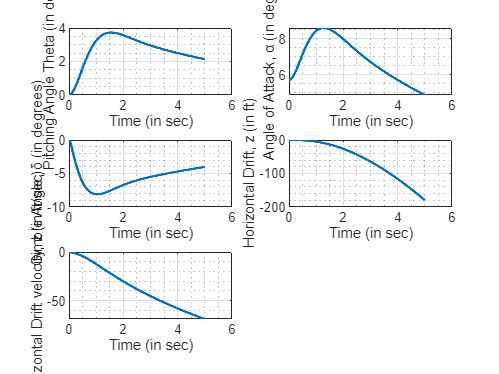

K =     1.9979    0.7987    3.6089


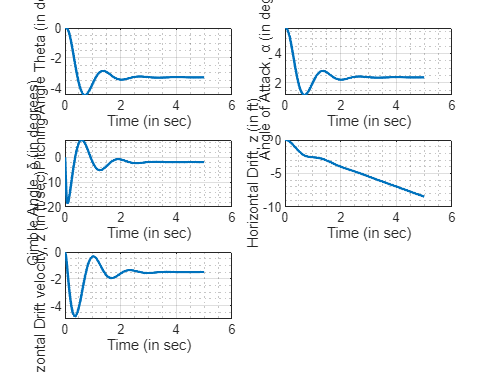

K =          0    0.7987    3.6089


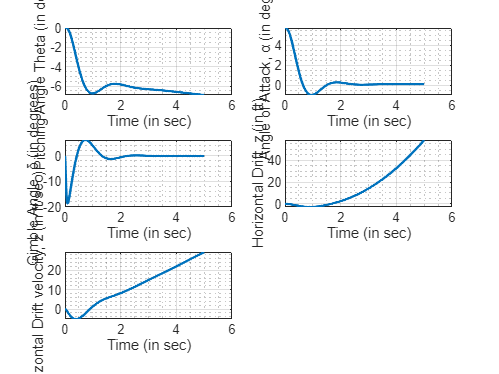

K =     0.6839    0.8474    0.9514


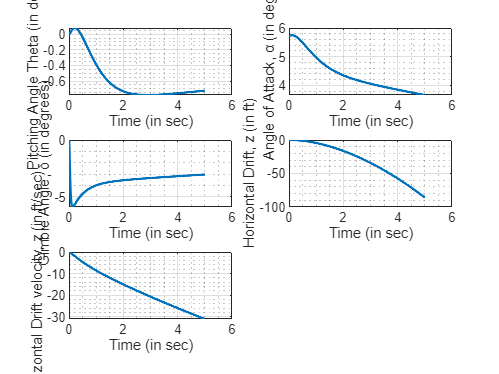

K =     0.3215    0.8335    1.2732


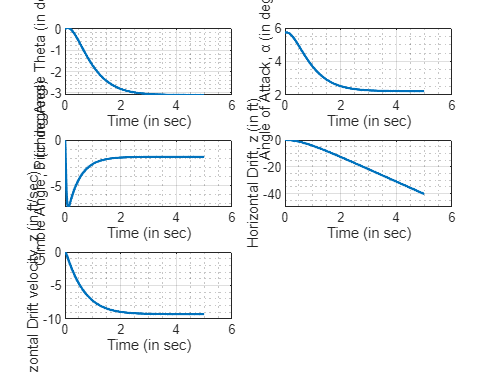

K =          0    0.8335    1.2732


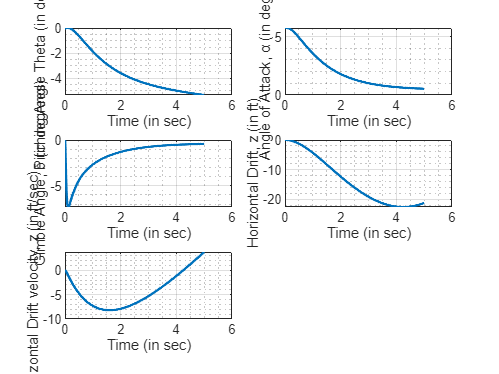

clear;
clc;
close all;

Iy = 2.43e6;
m = 5830;
T = 341000;
F = 375000;
x_cp = 38;
x_cg = 32.3;
V = 1320;
V_w = 132;
alpha_w = 5.73*pi/180;
N_alpha = 240000;
M_alpha = 3.75;
M_delta = 4.54;

Atheta = [0 1 0;0 0 M_alpha;-F/(m*V) 1 -N_alpha/(m*V)];
Btheta = [0;M_delta;T/(m*V)];
Ctheta = [1 0 0];
Dtheta = 0;

Kall = zeros([3 6]); 
%1. (Θ, Θdot)- feedback control
J = [-1.7488+1.3934j, -1.7488-1.3934j, -0.1596]; %Given desired close loop poles
Kall(:,1) = acker(Atheta,Btheta,J)';

%2. Drift Minimum control
K1 = Kall(1,1);
K2 = Kall(2,1);
K3 = (N_alpha*Kall(1,1)/F)*(1 + x_cp/x_cg) + (M_alpha/M_delta);
Kall(:, 2) = [K1; K2; K3];

%3. Load Minimum control
K1 = 0; %this is the condition for load minimum control
K2 = Kall(2,2);
K3 = Kall(3,2);
Kall(:,3) = [K1;K2;K3];

%4. using Linear Quadratic Regulator (Q = 0)
Q = 0;
R = 1;
[K, P, E] = lqr(Atheta, Btheta, Q,R);
Kall(:,4) = K';

%5. Drift minimum control
E = [E(2),E(3),0];
K = acker(Atheta, Btheta,E);
Kall(:,5) = K';

%6. Load Minimum Control
K = [0,K(2),K(3)];
Kall(:,6) = K';

%gimble actuator system
Adelta = [0 1;-2500 -100];
Bdelta = [0;2500];
Cdelta = [1 0];
Ddelta = 0;

% drift velocity
Adrift = [0 0 0 0 0 0 1;-(F/m) 0 -(N_alpha/m) (T/m) 0 0 0];

i = 1;
for K = Kall
    K = K'
    Afinal = [Atheta, Btheta*Cdelta, zeros([3,2]);-Bdelta*K, Adelta, zeros([2,2]);Adrift];
    
    
    t = 0:0.01:5;
    sys = ss(Afinal,eye(7),eye(7), eye(7));
    x = initial(sys, [0, 0, alpha_w, 0, 0, 0, 0], t);
    
    theta = [1 0 0 0 0 0 0]*x';
    alpha = [0 0 1 0 0 0 0]*x';
    delta = [0 0 0 1 0 0 0]*x';
    z = [0 0 0 0 0 1 0]*x';
    zdot = [0 0 0 0 0 0 1]*x';
    % zdot = -V*(theta + alpha_w*ones(size(t)) - alpha);
    figure(i);
    subplot(3, 2, 1)
    plot(t, theta*180/pi, LineWidth=1.5);
    grid on;grid minor;
    xlabel("Time (in sec)");
    ylabel("Pitching Angle Theta (in degrees)");
    
    subplot(3, 2, 2)
    plot(t, alpha*180/pi, LineWidth=1.5);
    grid on;grid minor;
    xlabel("Time (in sec)");
    ylabel("Angle of Attack, α (in degrees)");
    
    subplot(3, 2, 3)
    plot(t, delta*180/pi, LineWidth=1.5);
    grid on;grid minor;
    xlabel("Time (in sec)");
    ylabel("Gimble Angle, δ (in degrees)");
    
    subplot(3,2, 4)
    plot(t, z, linewidth=1.5);
    grid on;grid minor;
    xlabel("Time (in sec)");
    ylabel("Horizontal Drift, z (in ft)");
    
    subplot(3,2, 5)
    plot(t, zdot, linewidth=1.5);
    grid on;grid minor;
    xlabel("Time (in sec)");
    ylabel("Horizontal Drift velocity, z (in ft/sec)");

    i = i+1;
end